function observable(C, A)
    Ob = obsv(A, C);
    vpa(Ob, 4)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function controllable(A, B)
    Co = ctrb(A, B);
    vpa(Co, 4)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function K = get3K(A, B, G, Y)
    cvx_begin sdp quiet;
        variable P(size(A, 1), size(A, 1));
        A*P-P*G == B*Y;
    cvx_end;
    K = -Y*pinv(P);
    vpa(K, 4)
    eig(A+B*K)
end
function L = get3Lfull(A, C, G, Y)
    cvx_begin sdp quiet;
        variable Q(size(G, 1), size(A, 1))
        G*Q-Q*A == Y*C;
    cvx_end;
    L = pinv(Q)*Y;
    vpa(L, 4)
    eig(A+L*C)
end
function Q = get3Q(A, C, G, Y)
    cvx_begin sdp quiet;
        variable Q(size(G, 1), size(A, 1))
        G*Q-Q*A == Y*C;
    cvx_end;
    vpa(Q, 4)
end
% Определяем функцию для нелинейной системы
F = @(t, x, u, f) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
];
state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};

## ГЛАВА 1. ПОСТРОЕНИЕ МАТЕМАТИЧЕСКОЙ МОДЕЛИ ОБЪЕКТА

M = 487.29;
m = 8.12;
l = 3.50;
g = 9.81;
r = l/2;
J = m*l^2/12+m*r^2;
k = (M+m)*J-(m*r)^2;

A = [0 1 0 0; 0 0 (m*r)^2*g/k 0; 0 0 0 1; 0 0 (M+m)*g*m*r/k 0];
B = [0; J/k; 0; m*r/k];
D = [0; m*r/k; 0; (M+m)/k];
C = [1 0 0 0; 0 0 1 0];

## ГЛАВА 2. АНАЛИЗ МАТЕМАТИЧЕСКОЙ МОДЕЛИ

[V, ~] = eig(A);
vpa(sym(V), 4)
vpa(sym(eig(A)), 4)
observable(C, A)
controllable(A, B)
syms s;
I = eye(size(A, 1));
W = C*(s*I-A)^(-1)*B;
Wsimp = simplify(W);
vpa(Wsimp, 4)
[num, den] = numden(Wsimp(1, 1));
vpa(solve(sym(num), s), 4)
vpa(solve(sym(den), s), 4)
[num, den] = numden(Wsimp(2, 1));
vpa(solve(sym(num), s), 4)
vpa(solve(sym(den), s), 4)
syms s;
I = eye(size(A, 1));
W = C*(s*I-A)^(-1)*D;
Wsimp = simplify(W);
vpa(Wsimp, 4)
[num, den] = numden(Wsimp(1, 1));
vpa(solve(sym(num), s), 4)
vpa(solve(sym(den), s), 4)
[num, den] = numden(Wsimp(2, 1));
vpa(solve(sym(num), s), 4)
vpa(solve(sym(den), s), 4)
% Время моделирования
tspan = [0 2]; % Интервал времени [t0, tf]

% Набор начальных условий (близких к нулю)
initial_conditions = [
    0.1, 0.05, -0.02;
    -0.05, 0.1, 0.01;
    0.02, -0.03, 0.1;
    0.001, 0.001, -0.001
];

% Метки для состояний
state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Решаем ОДУ для каждого состояния
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j)';
        [t, x] = ode45(@(t, x) A * x, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i==2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/2.3.lin_free_t_low.png', 'Resolution', 500);
% Время моделирования
tspan = [0 10]; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Решаем ОДУ для каждого состояния
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j)';
        [t, x] = ode45(@(t, x) A * x, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i==2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/2.3.lin_free_t_high.png', 'Resolution', 500);
% Время моделирования
tspan = [0 2]; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Определяем функцию для нелинейной системы
f = 0;
u = 0;
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
];

% Решаем ОДУ для каждого состояния
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j)';
        [t, x] = ode45(F, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i==2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/2.3.nonlin_free_t_low.png', 'Resolution', 500);
% Время моделирования
tspan = [0 10]; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Решаем ОДУ для каждого состояния
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j)';
        [t, x] = ode45(F, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i==2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/2.3.nonlin_free_t_high.png', 'Resolution', 500);

## ГЛАВА 3. СТАБИЛИЗАЦИЯ МАЯТНИКА: МОДАЛЬНОЕ УПРАВЛЕНИЕ

Y1 = [1 1 1 1];
G1 = diag([-1 -2 -3 -4]);
observable(Y1, G1);
K = get3K(A, B, G1, Y1);
vpa(K, 4)
vpa(eig(A+B*K), 4)

% Время моделирования
tspan = [0 10]; % Интервал времени [t0, tf]

% Набор начальных условий
initial_conditions = [
    17  0.1 0.1 0.1;
    0.1 7   0.1 0.1;
    0.1 0.1 0.8 0.1;
    0.1 0.1 0.1 2.9
];

% Метки для состояний
state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

f = 0;

F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (K*x - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (K*x - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
];

% Решаем ОДУ для каждого состояния
done = 0;
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j);
        [t, x] = ode45(F, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
        if done == 0
            vpa(sym(x(size(x, 1)-1, :)), 4)
            ggg = K*x';
            [mmm, idxxx] = max(ggg)
            vpa(mmm)
        end
    end
    done = 1;
    legend('show', 'Location', 'northeast', 'Interpreter', 'latex');
end
exportgraphics(gcf, 'figs/3.1.good.png', 'Resolution', 500);
% Время моделирования
tspan = [0 2]; % Интервал времени [t0, tf]

% Набор начальных условий
initial_conditions = [
    40  0.1 0.1 0.1;
    0.1 12  0.1 0.1;
    0.1 0.1 1 0.1;
    0.1 0.1 0.1 4
];

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Решаем ОДУ для каждого состояния
done = 0;
num_states = size(initial_conditions, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    
    % Решаем для каждого набора начальных условий
    for j = 1:size(initial_conditions, 2)
        x0 = initial_conditions(:, j);
        [t, x] = ode45(F, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
        if done == 0
            vpa(sym(x(size(x, 1)-1, :)), 4)
        end
    end
    done = 1;
    legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
end
exportgraphics(gcf, 'figs/3.1.badd.png', 'Resolution', 500);

Y1 = [1 1 1 1];
G1 = diag([-1 -2 -3 -4]);
G2 = diag([-11,-2 -3 -4]);
G3 = diag([-11 -12 -3 -4]);
G4 = diag([-11 -12 -13 -4]);
G5 = diag([-11 -12 -13 -6]);
K1 = get3K(A, B, G1, Y1);
K2 = get3K(A, B, G2, Y1);
K3 = get3K(A, B, G3, Y1);
K4 = get3K(A, B, G4, Y1);
K5 = get3K(A, B, G5, Y1);
Ks = {K1, K2, K3, K4, K5};

% Время моделирования
tspan = [0 3]; % Интервал времени [t0, tf]

% Набор начальных условий
x0 = [
    0.1;
    0.1;
    0.1;
    0.1
];

% Метки для состояний
state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

f = 0;

energy = cell(size(Ks, 2), 1);

% Решаем ОДУ для каждого состояния
done = 0;
num_states = size(x0, 1);
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    % Решаем для каждого набора начальных условий
    for j = 1:size(Ks, 2)
        K = Ks{j};
        F = @(t, x) [
            x(2); % \dot{x}_1 = \dot{a}
            (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
            (J * (K*x - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
            x(4); % \dot{x}_3 = \dot{\varphi}
            1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
            (J * (K*x - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        ];
        [t, x] = ode45(F, tspan, x0);
        plot(t, x(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$K_{%d}$', j));
        if done == 0
            K
            ggg = K*x';
            [mmm, idxxx] = max(abs(ggg));
            t(idxxx)
            vpa(mmm)
            energy{j} = mmm;
            [mmm, idxxx] = max(abs(x(:, 1)));
            t(idxxx)
            vpa(mmm)
            [mmm, idxxx] = max(abs(x(:, 3)));
            t(idxxx)
            vpa(mmm)
        end
    end
    done = 1;
    if i==2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/3.2.sim.png', 'Resolution', 500);
vpa(energy, 4)
figure;
% Create a bar plot
numericData=cellfun(@double, energy)
bar(numericData);
% Customize x-axis labels
xticks(1:length(energy)); % Set x-ticks to the indices
xticklabels({'K1', 'K2', 'K3', 'K4', 'K5'}); % Set x-tick labels
% Add title and axis labels
ylabel('u max, H');
% Optional: Add grid
grid on;
% Add numeric values above each bar
for i = 1:length(numericData)
    text(i, numericData(i), sprintf('%.2f', numericData(i)), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 10);
end
exportgraphics(gcf, 'figs/3.2.sim_u.png', 'Resolution', 500);

Y1 = [1 1; 1 1; 1 1; 1 1];
G1 = diag([-1 -2 -3 -4]);
controllable(G1, Y1)
G2 = diag([-11,-2 -3 -4]);
G3 = diag([-11 -12 -3 -4]);
G4 = diag([-11 -12 -13 -4]);
G5 = diag([-11 -12 -13 -14]);
L1 = get3Lfull(A, C, G1, Y1);
L2 = get3Lfull(A, C, G2, Y1);
L3 = get3Lfull(A, C, G3, Y1);
L4 = get3Lfull(A, C, G4, Y1);
L5 = get3Lfull(A, C, G5, Y1);
Ls = {L1, L2, L3, L4, L5};

% Время моделирования
tspan = 0:0.01:1; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 425]);

% Набор начальных условий
x0 = [
    0.1; 0.1; 0.1; 0.1;
    0; 0; 0; 0
];
K = K1;
f = 0;
energy = cell(size(Ls, 2), 1);
xs = cell(size(Ls, 2), 1);
x_hats = cell(size(Ls, 2), 1);

% Simulate
num_states = size(x0, 1)/2;
for j = 1:size(Ls, 2)
    L = Ls{j};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        A * x(5:8) + B*u(x)+L*C*(x(5:8)-x(1:4));
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{j} = z(:, 1:4);
    x_hats{j} = z(:, 5:8);
end

% Решаем ОДУ для каждого состояния
done = 0;
num_states = size(x0, 1)/2;
for i = 1:num_states
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ls, 2)
        plot(tspan, x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    plot(tspan, xs{1}(:, i), '--', 'LineWidth', 1.5, 'DisplayName', sprintf('x'));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/3.3.full.png', 'Resolution', 500);

Y1 = [1 1; 1 1];
G1 = diag([-1 -2]);
controllable(G1, Y1)
G2 = diag([-6,-2]);
G3 = diag([-6 -4]);
L1 = get3Q(A, C, G1, Y1);
L2 = get3Q(A, C, G2, Y1);
L3 = get3Q(A, C, G3, Y1);
Qs = {L1, L2, L3};
Gs = {G1, G2, G3};

% Время моделирования
tspan = 0:0.01:1; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 425]);

% Набор начальных условий
x0 = [
    0.1; 0.1; 0.1; 0.1; % State
    0; 0;               % State of reduced estimator
];
Y = Y1;
K = K1;
f = 0;
energy = cell(size(Qs, 2), 1);
xs = cell(size(Qs, 2), 1);
x_hats = cell(size(Qs, 2), 1);

% Simulate
for j = 1:size(Qs, 2)
    Q = Qs{j};
    G = Gs{j};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        G*x(5:6) - Y*C*x(1:4)+Q*B*u(x); % z hat
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{j} = z(:, 1:4);
    x_hats{j} = (pinv([C; Q]) * [C*z(:, 1:4)'; z(:, 5:6)'])';
end

% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Qs, 2)
        plot(tspan, x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$Q_{%d}$', j));
    end
    plot(tspan, xs{1}(:, i), '--', 'LineWidth', 1.5, 'DisplayName', sprintf('x'));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/3.3.reduced.png', 'Resolution', 500);

% Время моделирования
tspan = 0:0.01:6; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 425]);

% Набор начальных условий
x0 = [
    0.1; 0.1; 0.1; 0.1; % State
    0; 0;               % State of reduced estimator
];
Y = Y1;
K = K1;
f = 0;
xs = cell(size(Qs, 2), 1);
x_hats = cell(size(Qs, 2), 1);

% Simulate
for j = 1:size(Qs, 2)
    Q = Qs{j};
    G = Gs{j};
    u = @(x) (K*(pinv([C; Q]) * [C*x(1:4); x(5:6)]));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        G*x(5:6) - Y*C*x(1:4)+Q*B*u(x); % z hat
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{j} = z(:, 1:4);
    x_hats{j} = (pinv([C; Q]) * [C*z(:, 1:4)'; z(:, 5:6)'])';
end

% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Qs, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$Q_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/3.4.wat.png', 'Resolution', 500);

% Время моделирования
tspan = 0:0.01:4; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 425]);

% Набор начальных условий
x0 = [
    0.1; 0.1; 0.1; 0.1; % State
    0; 0;               % State of reduced estimator
];
Y = Y1;
Q = Qs{1};
G = Gs{1};
f = 0;
xs = cell(size(Qs, 2), 1);
x_hats = cell(size(Qs, 2), 1);

% Simulate
for j = 1:(size(Ks, 2)-2)
    K = Ks{j};
    u = @(x) (K*(pinv([C; Q]) * [C*x(1:4); x(5:6)]));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        G*x(5:6) - Y*C*x(1:4)+Q*B*u(x); % z hat
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{j} = z(:, 1:4);
    x_hats{j} = (pinv([C; Q]) * [C*z(:, 1:4)'; z(:, 5:6)'])';
end

% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:(size(Ks, 2)-2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$K_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/3.4.watK.png', 'Resolution', 500);

% Время моделирования
tspan = 0:0.01:4; % Интервал времени [t0, tf]

% Создаем фигуру
figure('Position', [0, 0, 750, 425]);

% Набор начальных условий
x0 = [
    0.1; 0.1; 0.1; 0.1; % State
    0; 0;               % State of reduced estimator
];
Y = Y1;
Q = Qs{1};
G = Gs{1};
K = Ks{1};
f = 0;
xs = cell(size(Qs, 2), 1);
x_hats = cell(size(Qs, 2), 1);

% Simulate
u = @(x) (K*(pinv([C; Q]) * [C*x(1:4); x(5:6)]));
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    G*x(5:6) - Y*C*x(1:4)+Q*B*u(x); % z hat
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
x_hat = (pinv([C; Q]) * [C*z(:, 1:4)'; z(:, 5:6)']);
ggg = K*x_hat;
[mmm, idxxx] = max(ggg);
t(idxxx)
vpa(mmm)
[mmm, idxxx] = max(abs(x(:, 1)));
t(idxxx)
vpa(mmm)
[mmm, idxxx] = max(abs(x(:, 3)));
t(idxxx)
vpa(mmm)

% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
end
exportgraphics(gcf, 'figs/3.4.watQK.png', 'Resolution', 500);

## ГЛАВА 4. СТАБИЛИЗАЦИЯ МАЯТНИКА: РЕГУЛЯТОРЫ С ЗАДАННОЙ

## СТЕПЕНЬЮ УСТОЙЧИВОСТИ

function [K] = syntK(A, B, a)
    cvx_begin sdp quiet;
        variable P(size(A, 1), size(A, 1)) symmetric
        variable Y(size(B, 2), size(B, 1))
        P >= 0.0001*eye(size(A, 1));
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
    cvx_end
    K = Y*pinv(P);
    vpa(K, 4)
    vpa(eig(A+B*K), 2)
end

tspan = 0:0.01:6;

x0s = [
    7.4  0.1 0.1 0.1;
    0.1 4.3   0.1 0.1;
    0.1 0.1 0.5 0.1;
    0.1 0.1 0.1 1.3
];

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(x0s, 2));
f = 0;
K = syntK(A, B, 1);
% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(x0s, 2)
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    x0 = x0s(:, i);
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
end

% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(x0s, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.1.sim.png', 'Resolution', 500);

as = {0.01 1 4};
as_num = size(as, 2);
Ks = cell(1, as_num);
for i=1:as_num
    Ks{i} = syntK(A, B, as{i});
end

tspan = 0:0.01:6;

x0 = [
    0.1;
    0.1;
    0.1;
    0.1
];

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(Ks, 2));
f = 0;

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(Ks, 2)
    i
    K = Ks{i};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    ggg = K*z(:, 1:4)';
    [mmm, idxxx] = max(abs(ggg));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 1)));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 3)));
    t(idxxx)
    vpa(mmm)
end
% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ks, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$K_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.2.sim.png', 'Resolution', 500);

function [K] = syntKmin(A, B, a, x0)
    cvx_begin sdp quiet;
        variable P(size(A, 1), size(A, 1)) symmetric
        variable Y(size(B, 2), size(B, 1))
        variable mumu
        minimize mumu
        P > 0;  % 0.0001*eye(size(A, 1))
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
        [P x0;
         x0' 1] > 0;
        [P Y';
         Y mumu] > 0;
    cvx_end
    K = Y*pinv(P);
    vpa(K, 4)
    vpa(eig(A+B*K), 2)
end

x0s = {[0; 0.1; 0; 0]
    [0.01; 0; 0; 0]
    [0.001; 0.001; 0.0001; 0]};
as = {0.01 1};
as_num = size(as, 2);
Ks = cell(1, as_num);
for i=1:as_num
    Ks{i} = syntKmin(A, B, as{i}, x0s{i});
end

tspan = 0:0.01:600;

x0s = {[0; 0.1; 0; 0] [0.01; 0.11; 0.01; 0.01]};

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(x0s, 2));
f = 0;
K = Ks{1};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(x0s, 2)
    i
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    x0 = x0s{i};
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    ggg = K*z(:, 1:4)';
    [mmm, idxxx] = max(abs(ggg));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 1)));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 3)));
    t(idxxx)
    vpa(mmm)
end
% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(x0s, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.3.1.sim.png', 'Resolution', 500);

tspan = 0:0.01:6;

x0s = {[0.01; 0; 0; 0] [0.02; 0.01; 0.01; 0.01]};

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(x0s, 2));
f = 0;
K = Ks{2};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(x0s, 2)
    i
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    x0 = x0s{i};
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    ggg = K*z(:, 1:4)';
    [mmm, idxxx] = max(abs(ggg));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 1)));
    t(idxxx)
    vpa(mmm)
    [mmm, idxxx] = max(abs(xs{i}(:, 3)));
    t(idxxx)
    vpa(mmm)
end
% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(x0s, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.3.2.sim.png', 'Resolution', 500);

function [L] = get4L(A, C, a)
    cvx_begin sdp quiet;
        variable Q(size(A, 1), size(A, 1)) symmetric
        variable Y(size(C, 2), size(C, 1))
        Q >= 0.0001*eye(size(A, 1));
        A'*Q + Q*A + 2*a*Q + C'*Y' + Y*C <= 0;
    cvx_end
    L = pinv(Q)*Y;
    vpa(L, 4)
    vpa(eig(A+L*C), 2)
end
as = {0.01 1 4};
as_num = size(as, 2);
Ls = cell(1, as_num);
for i=1:as_num
    disp(i);
    Ls{i} = get4L(A, C, as{i});
end

tspan = 0:0.01:6;

x0 = [
    0.1;    0.1;    0.1;    0.1;
    0;0;0;0
];

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(Ls, 2));
x_hats = cell(1, size(Ls, 2));
f = 0;
K = Ks{2};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(Ls, 2)
    L = Ls{i};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        A * x(5:8) + B*u(x)+L*C*(x(5:8)-x(1:4));
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    x_hats{i} = z(:, 5:8);
end
% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ls, 2)
        plot(tspan, x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    plot(tspan, xs{j}(:, i), '--', 'LineWidth', 1.5, 'DisplayName', sprintf('$x$', j));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.5.sim.png', 'Resolution', 500);
figure('Position', [0, 0, 750, 525]);
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ls, 2)
        plot(tspan, xs{j}(:, i) - x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.5.sim.err.png', 'Resolution', 500);

tspan = 0:0.01:10;

x0 = [
    0.1;    0.1;    0.1;    0.1;
    0;0;0;0
];

state_labels = {"Координата", "Скорость", "Угол", "Угловая скорость"};
xs = cell(1, size(Ls, 2));
x_hats = cell(1, size(Ls, 2));
f = 0;
K = Ks{2};

% Создаем фигуру
figure('Position', [0, 0, 750, 525]);

% Simulate
for i = 1:size(Ls, 2)
    L = Ls{i};
    u = @(x) (K*x(5:8));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        A * x(5:8) + B*u(x)+L*C*(x(5:8)-x(1:4));
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    x_hats{i} = z(:, 5:8);
end
% Решаем ОДУ для каждого состояния
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ls, 2)
        plot(tspan, x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    plot(tspan, xs{j}(:, i), '--', 'LineWidth', 1.5, 'DisplayName', sprintf('$x$', j));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.6.sim.png', 'Resolution', 500);
figure('Position', [0, 0, 750, 525]);
for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(Ls, 2)
        plot(tspan, xs{j}(:, i) - x_hats{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/4.6.sim.err.png', 'Resolution', 500);

## ГЛАВА 5. СЛЕЖЕНИЕ И КОМПЕНСАЦИЯ

function [K2] = get_K2(A, B1, B2, G, C, D, K1)
    cvx_begin sdp
        variable P(size(A, 2), size(G, 1))
        variable Y(size(B1, 2), size(B2, 2))
        P*G-A*P==B1*Y+B2;
        C*P==-D;
    cvx_end
    K2 = Y-K1*P;
    vpa(K2, 4)
end
Gamma = [
    0 -1 0 0 0 0 0 0 0 0;
    1 0 0 0 0 0 0 0 0 0;
    0 0 0 -2 0 0 0 0 0 0;
    0 0 2 0 0 0 0 0 0 0;
    0 0 0 0 0 -4 0 0 0 0;
    0 0 0 0 4 0 0 0 0 0;
    0 0 0 0 0 0 0 -8 0 0;
    0 0 0 0 0 0 8 0 0 0;
    0 0 0 0 0 0 0 0 0 -16;
    0 0 0 0 0 0 0 0 16 0];
Y = [1 0 1 0 1 0 1 0 1 0];
w0 = [0; -1; 0.9; 0; 0; -0.8; 0.7; 0; 0; -0.6];

syms t
Y * expm(Gamma * t) * w0;

% Compute simplified symbolic expression
simplifiedExpr = rewrite(ans,"sincos")
sym(Gamma)
sym(Y)
sym(w0)
CZ = [0 0 1 0];
K1 = [797.9 1665.0 -19870.0 -9666.0];
K2 = get_K2(A, B, D*Y, Gamma, CZ, 0, K1);

tspan = 0:0.01:10;

x0 = [
    0.1; 0.1; 0.1; 0.1; w0
];

figure('Position', [0, 0, 750, 525]);

u = @(x) (K1*x(1:4)+K2*x(5:14));
F = @(t, x) [
    A*x(1:4)+B*u(x)+D*Y*x(5:14);
    Gamma * x(5:14);
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
w = z(:, 5:14);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
end
exportgraphics(gcf, 'figs/5.1.lin.png', 'Resolution', 500);
figure('Position', [0, 0, 750, 525]);

u = @(x) (K1*x(1:4)+K2*x(5:14));
f = @(x) (Y*x(5:14));
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f(x) + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    Gamma * x(5:14);
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
w = z(:, 5:14);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
end
exportgraphics(gcf, 'figs/5.1.nonlin.png', 'Resolution', 500);

Gamma = [
    0 -1 0 0 0 0 0 0 0 0;
    1 0 0 0 0 0 0 0 0 0;
    0 0 0 -2 0 0 0 0 0 0;
    0 0 2 0 0 0 0 0 0 0;
    0 0 0 0 0 -3 0 0 0 0;
    0 0 0 0 3 0 0 0 0 0;
    0 0 0 0 0 0 0 -4 0 0;
    0 0 0 0 0 0 4 0 0 0;
    0 0 0 0 0 0 0 0 0 -5;
    0 0 0 0 0 0 0 0 5 0];
Y = [1 0 0 1 1 0 0 1 1 0];
w0 = [0; -0.1; 0.09; 0; 0; -0.08; 0.07; 0; 0; -0.06];

syms t
Y * expm(Gamma * t) * w0;

% Compute simplified symbolic expression
simplifiedExpr = rewrite(ans,"sincos")
sym(Gamma)
sym(Y)
sym(w0)
CZ = [0 0 1 0];
DZ = -Y;
K1 = [797.9 1665.0 -19870.0 -9666.0];
K2 = get_K2(A, B, zeros(size(B, 1), size(Gamma, 2)), Gamma, CZ, DZ, K1);
tspan = 0:0.01:15;

x0 = [
    0.1; 0.1; 0.1; 0.1; w0
];

figure('Position', [0, 0, 750, 525]);

u = @(x) (K1*x(1:4)+K2*x(5:14));
F = @(t, x) [
    A*x(1:4)+B*u(x);
    Gamma * x(5:14);
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
w = z(:, 5:14);
sig = Y*w';

for i = 1:4
    subplot(3, 2, i);
    hold on;
    grid on;
    xlabel('Время, c');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
    if i==3
        plot(tspan, sig, '--', 'LineWidth', 1.5);
    end
end
subplot(3, 2, 5:6);
plot(tspan, sig' - x(:, 3), 'LineWidth', 1.5);
xlabel('Время, c');
ylabel("$g(t)-\varphi(t)$", "Interpreter", "latex");
title("Ошибка слежения");
grid on;
exportgraphics(gcf, 'figs/5.2.lin.png', 'Resolution', 500);
figure('Position', [0, 0, 750, 525]);

u = @(x) (K1*x(1:4)+K2*x(5:14));
f = @(x) (0);
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f(x) + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    Gamma * x(5:14);
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
w = z(:, 5:14);
sig = Y*w';

for i = 1:4
    subplot(3, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
    if i==3
        plot(tspan, sig, '--', 'LineWidth', 1.5);
    end
end
subplot(3, 2, 5:6);
plot(tspan, sig' - x(:, 3), 'LineWidth', 1.5);
xlabel('Время, c');
ylabel("$g(t)-\varphi(t)$", "Interpreter", "latex");
title("Ошибка слежения");
grid on;
exportgraphics(gcf, 'figs/5.2.nonlin.png', 'Resolution', 500);
tspan = 0:0.01:5;
figure('Position', [0, 0, 750, 525]);

w0 = [0; -1; 0.9; 0; 0; -0.8; 0.7; 0; 0; -0.6];
x0 = [
    0.1; 0.1; 0.1; 0.1; w0
];

u = @(x) (K1*x(1:4)+K2*x(5:14));
f = @(x) (0);
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f(x) + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f(x) + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    Gamma * x(5:14);
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
w = z(:, 5:14);
sig = Y*w';

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(tspan, x(:, i), 'LineWidth', 1.5);
    if i==3
        plot(tspan, sig, '--', 'LineWidth', 1.5);
    end
end
exportgraphics(gcf, 'figs/5.2.nonlin.bad.png', 'Resolution', 500);

## ГЛАВА 6. СТАБИЛИЗАЦИЯ МАЯТНИКА: LQR И ФИЛЬТР КАЛМАНА

function L = get6L(A, C, Q, R)
    [P,~,~] = icare(A', C', Q, R, [], [], []);    
    L = -P* C' * pinv(R);
    vpa(L, 4)
    vpa(eig(A+L*C), 5)
end
function K = get6K(A, B, Q, R)
    [P,~,~] = icare(A, B, Q, R, [], [], []);  
    K = -pinv(R) * B' * P;
    vpa(K, 4)
    vpa(eig(A+B*K), 5)
end
Qk = 100*eye(4);
Rk = 1;
K = get6K(A, B, Qk, Rk);
tspan = 0:0.01:60;

x0s = [
    563  0.1 0.1 0.1;
    0.1 45   0.1 0.1;
    0.1 0.1 1.2 0.1;
    0.1 0.1 0.1 5
];

xs = cell(1, size(x0s, 2));
f = 0;
u = @(x) (K*x(1:4));
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
];

figure('Position', [0, 0, 750, 525]);

for i = 1:size(x0s, 2)
    x0 = x0s(:, i);
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
end

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(x0s, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.1.sim.png', 'Resolution', 1000);
x0s = [
    564  0.1 0.1 0.1;
    0.1 46   0.1 0.1;
    0.1 0.1 1.3 0.1;
    0.1 0.1 0.1 6
];

xs = cell(1, size(x0s, 2));
f = 0;

figure('Position', [0, 0, 750, 525]);

for i = 1:size(x0s, 2)
    x0 = x0s(:, i);
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
end

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:size(x0s, 2)
        plot(tspan, xs{j}(:, i), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_{0%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.1.sim.bad.png', 'Resolution', 1000);

Qks = {
    [100 0 0 0; 0 100 0 0; 0 0 100 0; 0 0 0 100]
    [100 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
    [1 0 0 0; 0 1 0 0; 0 0 100 0; 0 0 0 1]
    [0.01 0 0 0; 0 0.01 0 0; 0 0 0.01 0; 0 0 0 0.01]
};
Rk = 1;
num = size(Qks, 1);
Ks = cell(1, num);
for i=1:num
    Ks{i} = get6K(A, B, Qks{i}, Rk);
end
tspan = 0:0.01:600;

x0 = [0.1;0.1;0.1;0.1];
xs = cell(1, size(x0s, 2));
us = cell(1, size(x0s, 2));
f = 0;

for i = 1:num
    i
    K = Ks{i};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    ggg = K*z(:, 1:4)';
    us{i} = ggg;
    [mmm, idxxx] = max(abs(ggg));
    vpa(mmm, 5)
    [mmm, idxxx] = max(abs(xs{i}(:, 1)));
    vpa(mmm, 2)
    [mmm, idxxx] = max(abs(xs{i}(:, 3)));
    vpa(mmm, 2)
end

figure('Position', [0, 0, 750, 525]);

for i = 1:2
    subplot(2, 1, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:num
        if mod(j, 2)==0
            plot(tspan, xs{j}(:, i), '--', 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
        else
            plot(tspan, xs{j}(:, i), 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
        end
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.2.sim.x.png', 'Resolution', 1000);
figure('Position', [0, 0, 750, 525]);
subplot(2,1,1);
hold on;
grid on;
xlabel('Время, с');
ylabel('u(t), Н');
for j = 1:num
    if mod(j, 2)==0
        plot(tspan(1, 1:500), us{j}(1, 1:500), '--', 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
    else
        plot(tspan(1, 1:500), us{j}(1, 1:500), 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
    end
end
legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
subplot(2,1,2);
hold on;
grid on;
xlabel('Время, с)');
ylabel('u(t), Н');
for j = 1:num
    if mod(j, 2)==0
        plot(tspan(1, 500:6001), us{j}(1, 500:6001), '--', 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
    else
        plot(tspan(1, 500:6001), us{j}(1, 500:6001), 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
    end
end
xlim([tspan(1, 500), tspan(1, 6001)]); % Set x-axis limits to start at 5 seconds
exportgraphics(gcf, 'figs/6.2.sim.u.png', 'Resolution', 1000);
tspan = 0:0.01:60;

x0 = [0.1;0.1;0.1;0.1];
xs = cell(1, size(x0s, 2));
f = 0;

for i = 1:num
    K = Ks{i};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
end

figure('Position', [0, 0, 750, 525]);

for i = 3:4
    subplot(2, 1, i-2);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:num
        if mod(j, 2)==0
            plot(tspan, xs{j}(:, i), '--', 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
        else
            plot(tspan, xs{j}(:, i), 'LineWidth', 2, 'DisplayName', sprintf('$K_{%d}$', j));
        end
    end
    if i == 4
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.2.sim.phi.png', 'Resolution', 1000);

K = [10.0 109.7 -10720.0 -5198.0];
Qks = {
    [100 0 0 0; 0 100 0 0; 0 0 100 0; 0 0 0 100]
    [0.01 0 0 0; 0 0.01 0 0; 0 0 0.01 0; 0 0 0 0.01]
};
Rk = 1;
num = size(Qks, 1);
Ls = cell(1, num);
for i=1:num
    Ls{i} = get6L(A, C, Qks{i}, Rk);
end

$$ans = \left(\begin{array}{cc} -10.95 & -0.007686\\ -10.0 & -0.1468\\ -0.007686 & -11.41\\ -0.02512 & -15.12 \end{array}\right)$$

$$ans = \left(\begin{array}{c} -9.9493\\ -10.364\\ -1.0051\\ -1.0487 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -0.4605 & -0.09494\\ -0.1056 & -0.2394\\ -0.09494 & -4.126\\ -0.196 & -8.51 \end{array}\right)$$

$$ans = \left(\begin{array}{c} -0.22918+0.21799\,\mathrm{i}\\ -0.22918-0.21799\,\mathrm{i}\\ -2.0201\\ -2.1077 \end{array}\right)$$

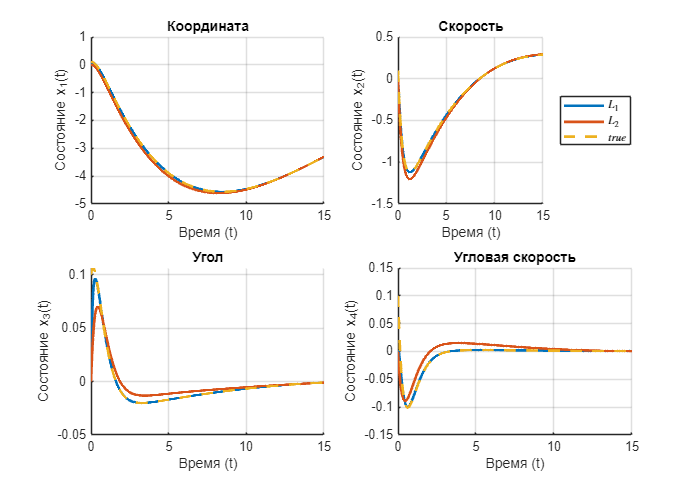

tspan = 0:0.01:15;

x0 = [0.1;0.1;0.1;0.1;0;0;0;0];
xs = cell(1, num);
x_hats = cell(1, num);
f = 0;

for i = 1:num
    L = Ls{i};
    u = @(x) (K*x(1:4));
    F = @(t, x) [
        x(2); % \dot{x}_1 = \dot{a}
        (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
        x(4); % \dot{x}_3 = \dot{\varphi}
        1 / J * (f + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
        (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
        A * x(5:8) + B*u(x)+L*C*(x(5:8)-x(1:4));
    ];
    [t, z] = ode45(F, tspan, x0);
    xs{i} = z(:, 1:4);
    x_hats{i} = z(:, 5:8);
end

figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    for j = 1:num
        plot(tspan, x_hats{j}(:, i), 'LineWidth', 2, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    plot(tspan, xs{j}(:, i), '--', 'LineWidth', 2, 'DisplayName', sprintf('$true$'));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.3.sim.png', 'Resolution', 1000);

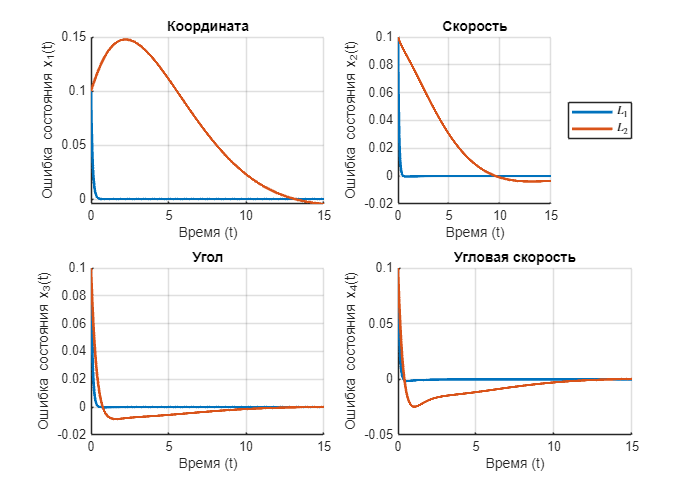

figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Ошибка состояния x_%d(t)', i));
    title(state_labels{i});
    for j = 1:num
        plot(tspan, xs{j}(:, i) - x_hats{j}(:, i), 'LineWidth', 2, 'DisplayName', sprintf('$L_{%d}$', j));
    end
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, 'figs/6.3.sim.err.png', 'Resolution', 1000);

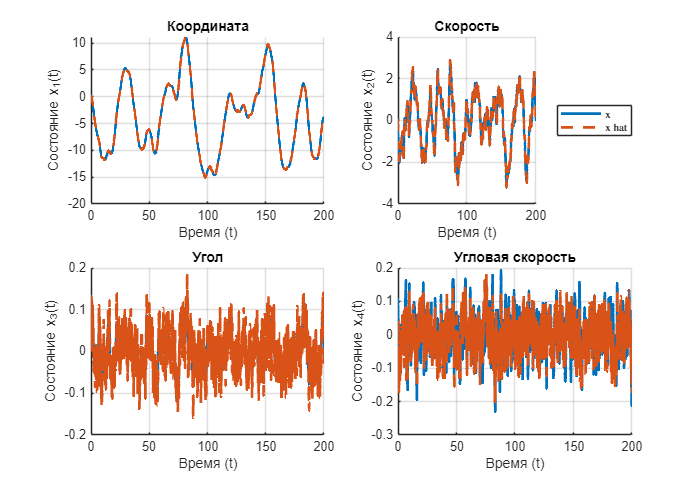

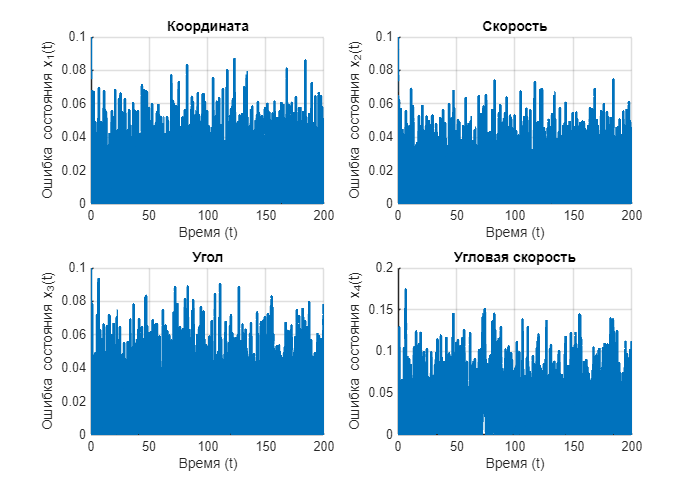

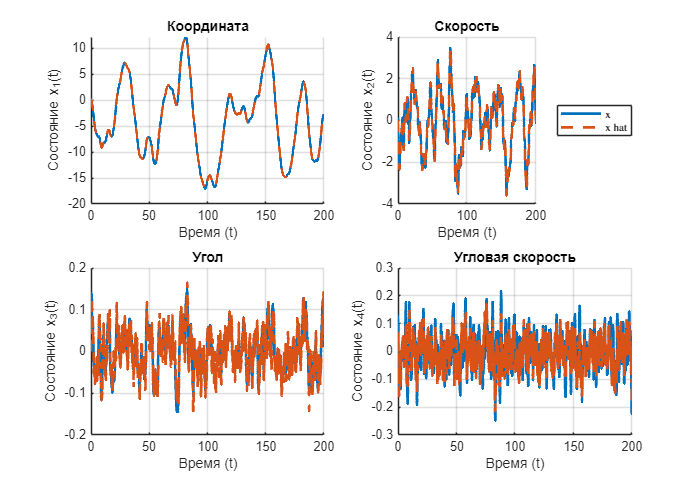

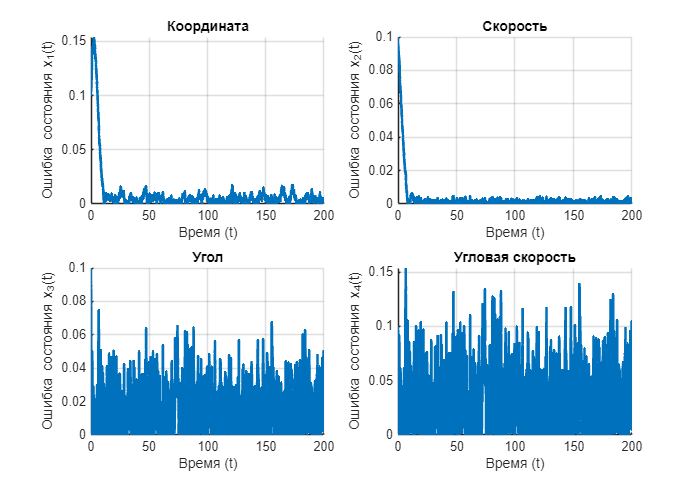

rng('default')  % For reproducibility

tspan = 0:0.01:200;

f = mvnrnd(0, 0.1, size(tspan, 2));
xi = mvnrnd([0 0],[0.01 0; 0 0.01], size(tspan, 2));
f_interp = @(t) interp1(tspan, f, t, 'linear', 'extrap');
xi_interp = @(t) interp1(tspan, xi, t, 'linear', 'extrap');

x0 = [0.1;0.1;0.1;0.1;0;0;0;0];

for m=1:num
L = Ls{m};
u = @(x) (K*x(5:8));
F = @(t, x) [
    A*x(1:4) + B*u(x)+D*f_interp(t);
    A*x(5:8) + B*u(x)+L*(C*x(5:8)-C*x(1:4)-xi_interp(t)');
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
x_hat = z(:, 5:8);

figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(t, x(:, i), 'LineWidth', 2, 'DisplayName', sprintf('x'));
    plot(t, x_hat(:, i), '--', 'LineWidth', 2, 'DisplayName', sprintf('x hat'));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, sprintf('figs/6.4.sim.%d.png', m), 'Resolution', 1000);
figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Ошибка состояния x_%d(t)', i));
    title(state_labels{i});
    plot(t, abs(x(:, i) - x_hat(:, i)), 'LineWidth', 2);
end
exportgraphics(gcf, sprintf('figs/6.4.sim.%d.err.png', m), 'Resolution', 1000);
end

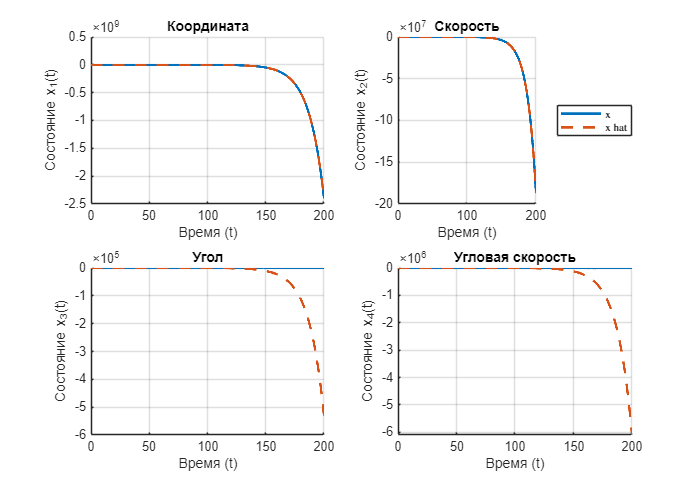

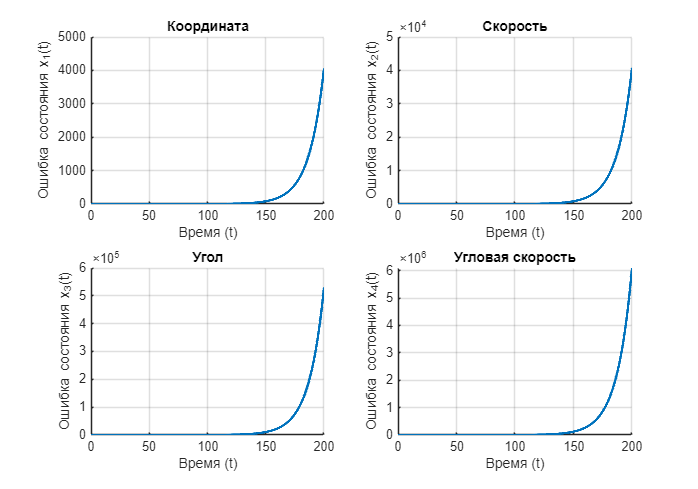

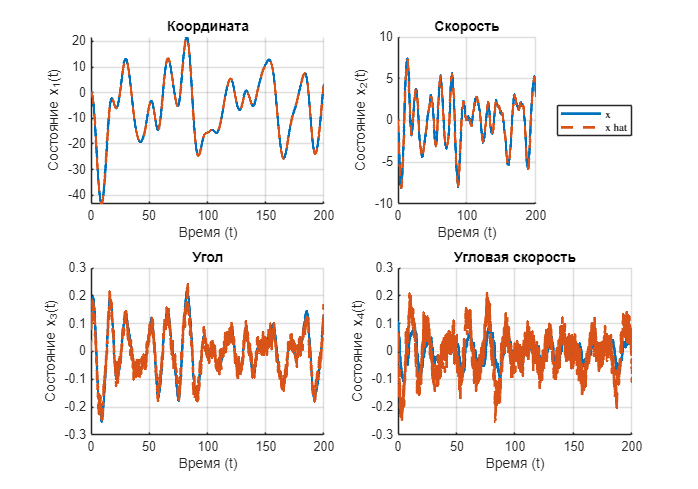

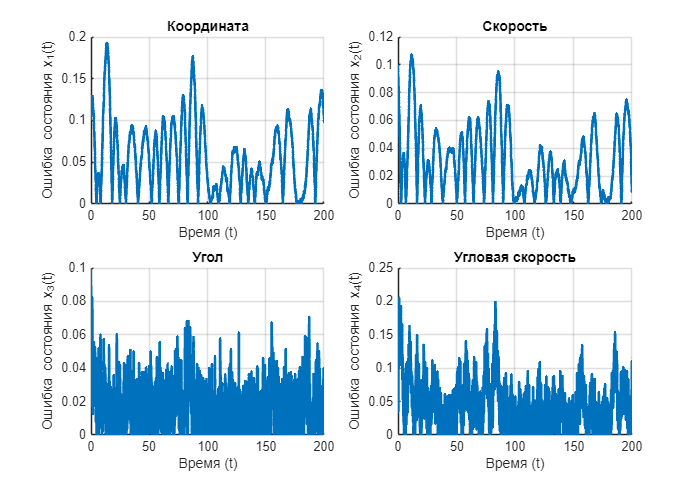

rng('default')  % For reproducibility

tspan = 0:0.01:200;

f = mvnrnd(0, 0.1, size(tspan, 2));
xi = mvnrnd([0 0],[0.01 0; 0 0.01], size(tspan, 2));
f_interp = @(t) interp1(tspan, f, t, 'linear', 'extrap');
xi_interp = @(t) interp1(tspan, xi, t, 'linear', 'extrap');

x0 = [0.1;0.1;0.1;0.1;0;0;0;0];

for m=1:num
L = Ls{m};
u = @(x) (K*x(5:8));
F = @(t, x) [
    x(2); % \dot{x}_1 = \dot{a}
    (1 / ((M + m) * J - (m * r * cos(x(3)))^2)) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f_interp(t) + m*r*g * sin(x(3))) * m * r * cos(x(3))); % \dot{x}_2 = F_2
    x(4); % \dot{x}_3 = \dot{\varphi}
    1 / J * (f_interp(t) + m*r*g * sin(x(3)) + m*r*cos(x(3)) / ((M + m) * J - (m * r * cos(x(3)))^2) * ...
    (J * (u(x) - m * r * x(4)^2 * sin(x(3))) + (f_interp(t) + m*r*g * sin(x(3))) * m * r * cos(x(3)))); % \dot{x}_4 = F_4
    A*x(5:8) + B*u(x)+L*(C*x(5:8)-C*x(1:4)-xi_interp(t)');
];
[t, z] = ode45(F, tspan, x0);
x = z(:, 1:4);
x_hat = z(:, 5:8);

figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Состояние x_%d(t)', i));
    title(state_labels{i});
    plot(t, x(:, i), 'LineWidth', 2, 'DisplayName', sprintf('x'));
    plot(t, x_hat(:, i), '--', 'LineWidth', 2, 'DisplayName', sprintf('x hat'));
    if i == 2
        legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
    end
end
exportgraphics(gcf, sprintf('figs/6.5.sim.%d.png', m), 'Resolution', 1000);
figure('Position', [0, 0, 750, 525]);

for i = 1:4
    subplot(2, 2, i);
    hold on;
    grid on;
    xlabel('Время (t)');
    ylabel(sprintf('Ошибка состояния x_%d(t)', i));
    title(state_labels{i});
    plot(t, abs(x(:, i) - x_hat(:, i)), 'LineWidth', 2);
end
exportgraphics(gcf, sprintf('figs/6.5.sim.%d.err.png', m), 'Resolution', 1000);
end